# DC Motor System Identification 

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

R = 34;         % Electrical Resistance of motor in Ohms
V_max = 6.89;   % Maximum Electrical Voltage applied to motor
Ts = 0.01;      % Sampling Time for system

% Initial Guesses at Optimization Variables
L0 = 1;
J0 = 1;
b0 = 1;
Km0 = 1;

% Load Motor Test Data Here
% TODO: Add load function files
t = 1;
signal = 1;
Voltage = signal/max(abs(signal))*V_max;    % Converts into Volts
speed = 1 ./ (Ts * 14 * 20) * 2 * pi();     % Converts into rad/s

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

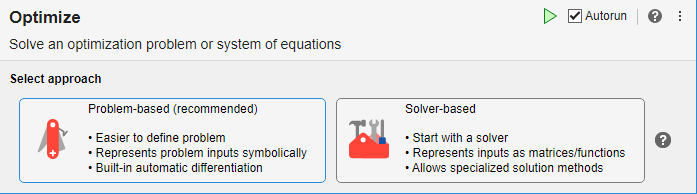

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
J7 = optimvar("J","LowerBound",0);
L7 = optimvar("L","LowerBound",0);
b7 = optimvar("b","LowerBound",0);
Km7 = optimvar("Km","LowerBound",0);

% Set initial starting point for the solver
initialPoint6.J = J0;
initialPoint6.L = L0;
initialPoint6.b = b0;
initialPoint6.Km = Km0;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@minResidual,J7,L7,b7,R,Km7,t,Voltage,speed);

Error using DynamicSystem/lsim
When simulating the response to a specific input signal, the input data U must be a matrix with as many rows as samples in the time vector T, and as many columns as input channels.

Error in SystemIDOptimizer>minResidual (line 75)
w_sim = lsim(dcMotorStatespace,V,t,[0 0],'zoh');

Error in optim.problemdef.fcn2optimexpr

Error in optim.problemdef.fcn2optimexpr

Error in fcn2optimexpr

Caused by:
    Function evaluation failed while attempting to determine output si


% Display problem information
show(problem);

% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint6);

% Display results
solution
reasonSolverStopped
objectiveValue

% Clear variables
clearvars J7 L7 b7 Km7 initialPoint6 reasonSolverStopped objectiveValue

## Interpret Results

Plot the data and the fitted model response

% Get optimal parameters
J_opt = solution.J;
L_opt = solution.L;
b_opt = solution.b;
Km_opt = solution.Km;

% Build statespace model from optimal fit parameters
h1 = tf(Km_opt, [L_opt R]);
h2 = tf(1 , [J_opt b_opt]);
dcMotorStatespace = ss(h2, [h1, 1]);
dcMotorStatespace = feedback(dcMotorStatespace,Km_opt, 1, 1);

% Compute simulated response and plot
w_sim = lsim(dcMotorStatespace,Voltage,t,[0 0],'zoh');
plot(t,speed);
hold on;
plot(t,w_sim);

## Helper Functions

function objective = minResidual(J,L,b,R,Km,t,V,w)
% This function should return a scalar representing an optimization objective.

% Build statespace model
h1 = tf(Km, [L R]);
h2 = tf(1 , [J b]);
dcMotorStatespace = ss(h2) * [h1, 1];
dcMotorStatespace = feedback(dcMotorStatespace,Km, 1, 1);

% Compute state space model response to signal
w_sim = lsim(dcMotorStatespace,V,t,[0 0],'zoh');

% Compute sum squared error between statespace and actual data
objective = sum((w_sim - w).^2);
end
